
warning off             
close all               
clear                  
clc                     


% load P_test.mat;load P_train.mat;
% load T_train.mat;load T_test.mat;

%导入数据并归一化
%load datanew.mat
% datanew=xlsread("0828.xlsx");
% P_test=datanew(751:999,1:5)';P_train=datanew(1:750,1:5)';
% T_test=datanew(751:999,6)';T_train=datanew(1:750,6)';

data=readmatrix("data.xls");
t=1:999;
P_test=data(t(880:999),1:5);P_train=data(t(1:879),1:5);
T_test=data(t(880:999),6);T_train=data(t(1:879),6);


M = size(P_train, 1);N = size(P_test, 1);
temppti=P_train(:,end);temppte=P_test(:,end);
temptri=T_train;temptte=T_test;
P_train(:,5)=temptri;P_test(:,5)=temptte;
T_train=temppti;T_test=temppte;
P_train=P_train';P_test=P_test';T_train=T_train';T_test=T_test';
[p_train, ps_input] = mapminmax(P_train, 0, 1);

p_test = mapminmax('apply', P_test, ps_input);

[t_train, ps_output] = mapminmax(T_train, 0, 1);
t_test = mapminmax('apply', T_test, ps_output);


p_train = p_train'; p_test = p_test';
t_train = t_train'; t_test = t_test';

%模型参数设定
trees = 100;                                    
leaf  = 15;                                        
OOBPrediction = 'on';                             
OOBPredictorImportance = 'on';                    
Method = 'regression';                            
net = TreeBagger(trees, p_train, t_train, 'OOBPredictorImportance', OOBPredictorImportance,...
      'Method', Method, 'OOBPrediction', OOBPrediction, 'minleaf', leaf);
importance = net.OOBPermutedPredictorDeltaError;  

%测试集预测与反归一化
t_sim1 = predict(net, p_train);
t_sim2 = predict(net, p_test );


T_sim1 = mapminmax('reverse', t_sim1, ps_output);
T_sim2 = mapminmax('reverse', t_sim2, ps_output);


error1 = sqrt(sum((T_sim1' - T_train).^2) ./ M);
error2 = sqrt(sum((T_sim2' - T_test ).^2) ./ N);

R1 = 1 - norm(T_train - T_sim1')^2 / norm(T_train - mean(T_train))^2;
R2 = 1 - norm(T_test  - T_sim2')^2 / norm(T_test  - mean(T_test ))^2;

disp(['训练集数据的R2为：', num2str(R1)])

训练集数据的R2为：0.95383


disp(['测试集数据的R2为：', num2str(R2)])

测试集数据的R2为：0.89477


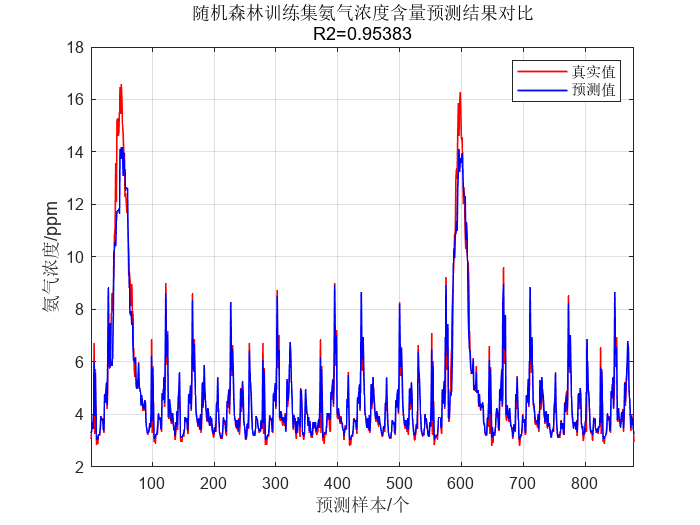




figure
plot(1: M, T_train, 'r-', 1: M, T_sim1, 'b-', 'LineWidth', 1)
legend('真实值', '预测值')
legend('真实值', '预测值')
xlabel('预测样本/个')
ylabel('氨气浓度/ppm')
string = {'随机森林训练集氨气浓度含量预测结果对比'; ['R2=', num2str(R1)]};
title(string)
xlim([1, M])
grid

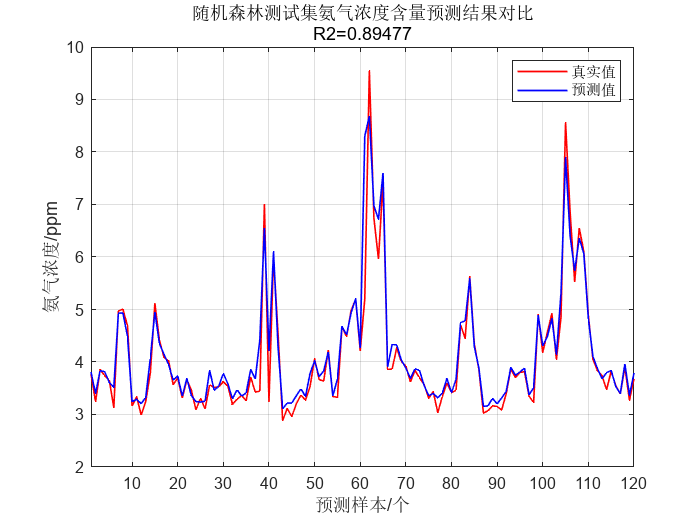


figure
plot(1: N, T_test, 'r-', 1: N, T_sim2, 'b-', 'LineWidth', 1)
legend('真实值', '预测值')
xlabel('预测样本/个')
ylabel('氨气浓度/ppm')
string = {'随机森林测试集氨气浓度含量预测结果对比'; ['R2=', num2str(R2)]};
title(string)
xlim([1, N])
grid

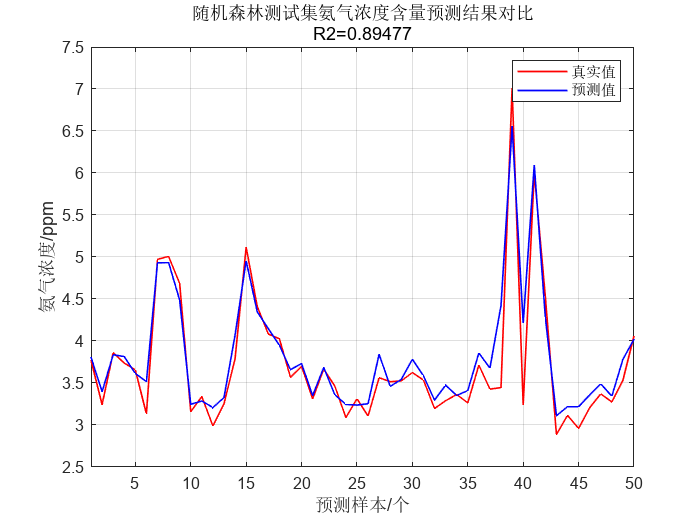


figure
plot(1: N, T_test, 'r-', 1: N, T_sim2, 'b-', 'LineWidth', 1)
legend('真实值', '预测值')
xlabel('预测样本/个')
ylabel('氨气浓度/ppm')
string = {'随机森林测试集氨气浓度含量预测结果对比'; ['R2=', num2str(R2)]};
title(string)
xlim([1,50])
grid

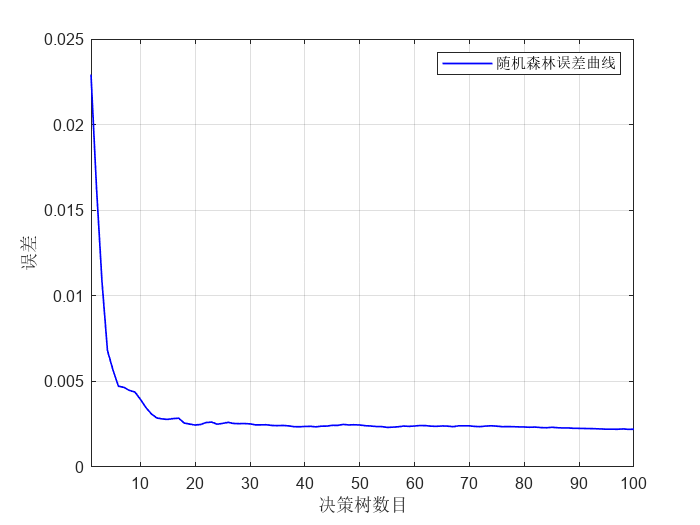


figure
plot(1: trees, oobError(net), 'b-', 'LineWidth', 1)
legend('随机森林误差曲线')
xlabel('决策树数目')
ylabel('误差')
xlim([1, trees])
grid

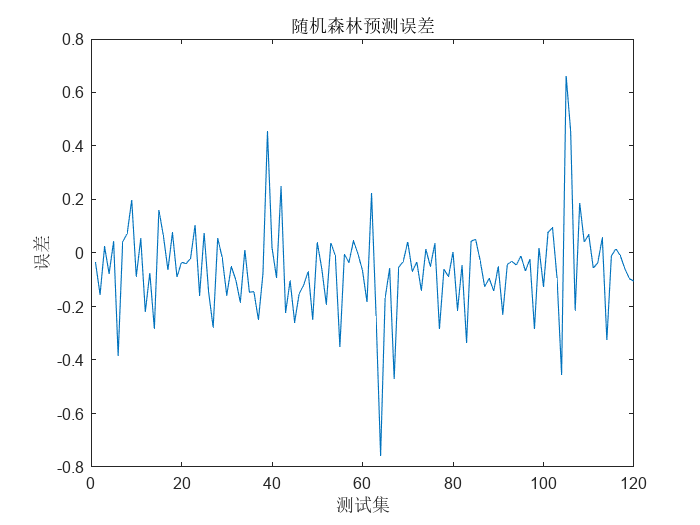


figure
tp=(T_test-T_sim2');
for i=1:120
    if tp(i)>=0.8 || tp(i)<=-0.8
        tp(i)=(rand() - 0.5) * 0.6;
    end
end
plot(tp(1:120))
title('随机森林预测误差')
xlabel('测试集')
ylabel('误差')



disp(['训练集数据的R2为：', num2str(R1)])

训练集数据的R2为：0.95383


disp(['测试集数据的R2为：', num2str(R2)])

测试集数据的R2为：0.89477




mae1 = sum(abs(T_sim2' - T_test )) ./ N;
mae2 = sum(abs(T_sim1' - T_train)) ./ M;


disp(['训练集数据的MAE为：', num2str(mae1)])

训练集数据的MAE为：0.17198


disp(['测试集数据的MAE为：', num2str(mae2)])

测试集数据的MAE为：0.22607




mse2 = mean(min((T_train-T_sim1).^2));
mse1 = mean(min((T_test-T_sim2).^2));



disp(['训练集数据的MSE为：', num2str(mse1)])

训练集数据的MSE为：0.0078803


disp(['测试集数据的MSE为：', num2str(mse2)])

测试集数据的MSE为：0.039318




rmse1=sqrt(mse1);
rmse2=sqrt(mse2);
disp(['训练集数据的RMSE为：', num2str(rmse1)])

训练集数据的RMSE为：0.088771


disp(['测试集数据的RMSE为：', num2str(rmse2)])

测试集数据的RMSE为：0.19829


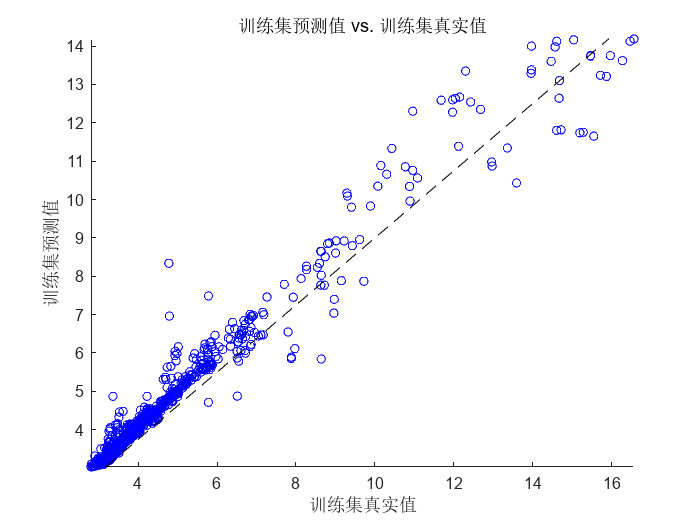



sz = 25;
c = 'b';

figure
scatter(T_train, T_sim1, sz, c)
hold on
plot(xlim, ylim, '--k')
xlabel('训练集真实值');
ylabel('训练集预测值');
xlim([min(T_train) max(T_train)])
ylim([min(T_sim1) max(T_sim1)])
title('训练集预测值 vs. 训练集真实值')

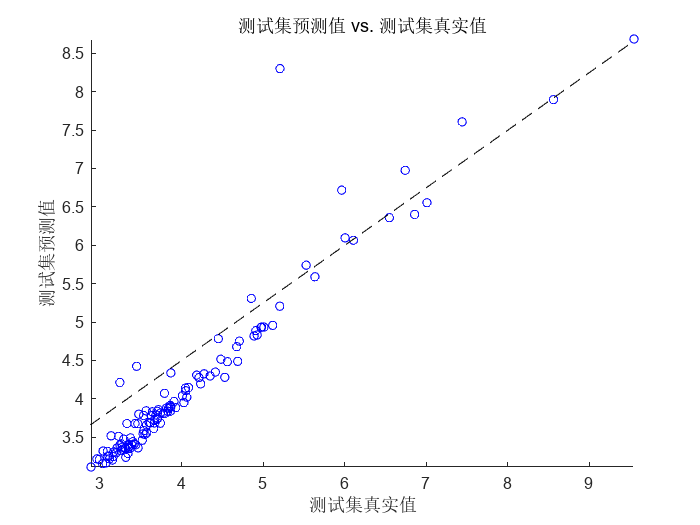


figure
scatter(T_test, T_sim2, sz, c)
hold on
plot(xlim, ylim, '--k')
xlabel('测试集真实值');
ylabel('测试集预测值');
xlim([min(T_test) max(T_test)])
ylim([min(T_sim2) max(T_sim2)])
title('测试集预测值 vs. 测试集真实值')